# LightSim experiments using Color Performance Review (CPR)

For London Imaging Meeting 2022 Work-in-Progress Poster Submission

WCC 6/10/2022

Evironment Dependency

userpath = 'C:\Users\wayne\Documents\GitHub\';
%userpath = 'C:\Users\wcc\Documents\GitHub\';
classpath = [userpath 'MIS_acquire\@LightSim\'];

addpath([userpath 'color_performance_review'])
addpath([userpath 'color_conversion'])

Data files for NEC

% NEC
fn_cs2000 = [classpath '0605\colorchecker_test_result_nec.mat'];
fn_cl500a = [classpath 'cl500a_0608\CL500a_nec.xlsx'];
fn_i1 = [classpath 'nec_i1_0608\i1data_nec.mat'];
fn_spyder = [classpath 'nec_0607\spyder_nec.mat'];

Data files for HP

% HP
fn_cs2000 = [classpath '0605\colorchecker_test_result_hp.mat'];
fn_cl500a = [classpath 'cl500a_0608\CL500a_hp.xlsx'];
fn_i1 = [classpath 'hp_i1_0608\i1data_hp.mat'];
fn_spyder = [classpath 'hp_0606\spyder0606.mat'];

Data files for Rift

% Rift
fn_cs2000 = [classpath '0605\colorchecker_test_result_rift.mat'];
fn_cl500a = [classpath 'cl500a_0608\CL500a_rift.xlsx'];
fn_i1 = [classpath 'rift_i1_0608\i1data_rift.mat'];
fn_spyder = [classpath 'rift0607\spyder_rift.mat'];

Create the objects

data_cs2000 = DeviceData;
data_cl500a = DeviceData;
data_i1 = DeviceData;
data_lightsim = DeviceData;
data_spyder = DeviceData;

data_cs2000.construct_by_cs2000(fn_cs2000)
data_lightsim.construct_by_target(fn_cs2000)
data_cl500a.construct_by_CL500a(fn_cl500a)

data_i1.construct_by_i1(fn_i1)
data_spyder.construct_by_spyder(fn_spyder,3)

## Evaluate Spyder X

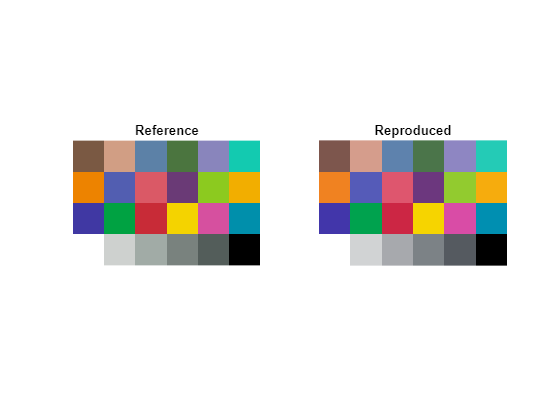

a=data_cs2000;
b=data_spyder;
cpr = CPR.ColorPerformanceReview(1);
clf; cpr.evaluate_visual(a,b);

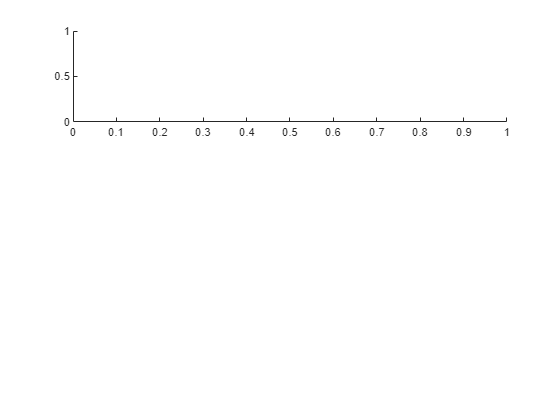

Index in position 2 exceeds array bounds.

Error in CPR.ColorPerformanceReview/evaluate_order_lightness (line 380)
            patchid = obj.ilablchJoint(:,1);

Error in CPR.ColorPerformanceReview/evaluate_order (line 369)
            obj.evaluate_

clf; cpr.evaluate_order(a,b);

clf; cpr.show3dquiver(a,b); view([12 32])
clf; cpr.evaluate_dE(a,b);
clf; cpr.evaluate_CCE(a,b);

## Evaluate LightSim

a=data_lightsim;
b=data_cs2000;
cpr = CPR.ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);
clf; cpr.evaluate_order(a,b);
clf; cpr.show3dquiver(a,b); view([12 32])
clf; b.compare_with_ref(a)
clf; cpr.evaluate_dE(a,b);
clf; cpr.evaluate_CCE(a,b);

## Evaluate CL500A

a=data_cs2000;
b=data_cl500a;
cpr = CPR.ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);
clf; cpr.evaluate_order(a,b);
clf; cpr.show3dquiver(a,b); view([12 32])
clf; b.compare_with_ref(a)
clf; cpr.evaluate_dE(a,b);
clf; cpr.evaluate_CCE(a,b);

## Evaluate EyeOne Pro

a=data_cs2000;
b=data_i1;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);
clf; cpr.evaluate_order(a,b);
clf; cpr.show3dquiver(a,b); view([12 32])
clf; b.compare_with_ref(a)
clf; cpr.evaluate_dE(a,b);
clf; cpr.evaluate_CCE(a,b);